# Optimal Stress and Strain

In this exercise we'll use optimzation to discover the "best" fit between a model of the stress strain relationship and experimental data.  You are provided with a dataset from a materials science experiment and find fit the parameters of an empircal model to explain the relationship by finding model parameters to minimize the error between the data and the model.

## Experimental Data

From tensile experiments on carbon steel, we have the following data.

% Strain [mm/mm]
strain_exp = [0, 0.0023809 0.003749347, 0.005234888, ...
    0.007631515, 0.011446096, 0.017384888, ...
    0.026405375, 0.039775799];
% Stress [MPa]
stress_exp = [0, 500, 550, 600, 660, 720, 780, 840, 900];

Plot the data (strain on the x-axis, stress on the y-axis) to get a sense of the relationship.

figure;
clf;
plot(strain_exp, stress_exp,'bo')

## Model: Ramberg-Osgood Equation

One model that we can use to explain the data is the Ramberg-Osgood equation:


$$\epsilon = \frac{\sigma}{E} + \left(\frac{\sigma}{K}\right)^n$$


The Young's modules for the material is known:


$$E = 210,000 \:\: \text{MPa}$$


but the coefficients $K$and $n$ are unknown.

Write a local function to implement the Ramberg-Osgood equation with the following signature:

where `params` is a two element vector for the parameters $K$and $n$ in that order.

function strain = ROE(stress, params)
    K = params(1);
    n = params(2);
    E = 210000;
    strain = stress./E + (stress./K).^n;
end

### Test the model function

Test your function with nominal values of $K = 1000$ MPA and $n = 7$.  First test for a scalar value of stress, say 500 MPA.

params = [1000, 5];
strain = ROE(500, params)

strain =    0.033630952380952


From the data, the corresponding strain value is 0.0023 mm/mm.  Does the function give you reasonable value?

Next test your function with the same nominal parameters for K and n, but for all the experimental values of stress.  The function should be able to take the vector `stress_exp` as an argument and return an array of strain values using array (element-wise) arithmetic.

strain = ROE(stress_exp, params);

Plot the results on the same axis you used for the experimental data.   You should see that the shape generated by the model is similar to the shape of the date, but that it is a very poor fit.

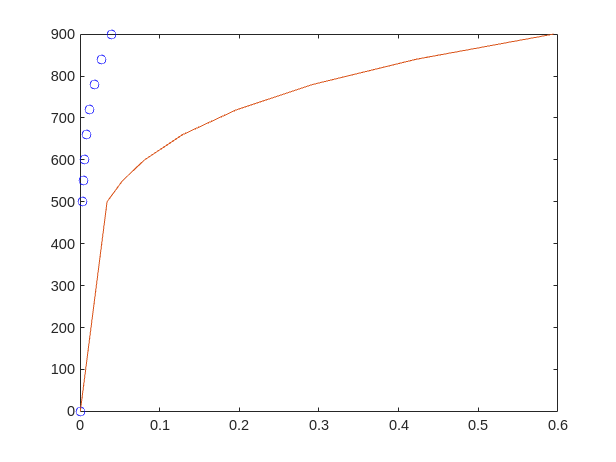

MSE =    0.066488662713100


hold on
plot(strain, stress_exp);

## Optimization Formulation

If we want to use an optimizaiton algorithm to find the "best" fit, we need to tell it what we mean by "best".  We do this by formulating a cost function.  

### Cost Function

The Mean-Squared Error (MSE)  cost function is popular for expressing this intent:


$$\text{MSE} = \frac{1}{m} \sum_{i=1}^m \left( y_i - f(x_i) \right)^2
$$


- The total cost, the scalar we want to minimize.

- $m$ is the number of data points

- $y_i$ is the observed value at the i-th data point

- $f(x_i)$ is the predicted value from the Ramberg-Osgood model.

How are we doing so far?  For our current fit, with $K = 1000$ MPA and $n = 7$, find the MSE.

MSE = sum((strain-strain_exp).^2)/length(strain_exp)

### Formulation or fminsearch interface.

We have all the pieces, but now need to get them together into a form that we can pass to `fminsearch`.

Here is the documentation of the interface:

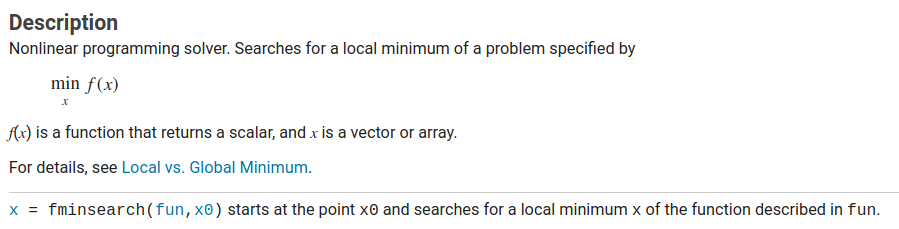

We need to experess the prolbem as a single function, which we pass as a handle.

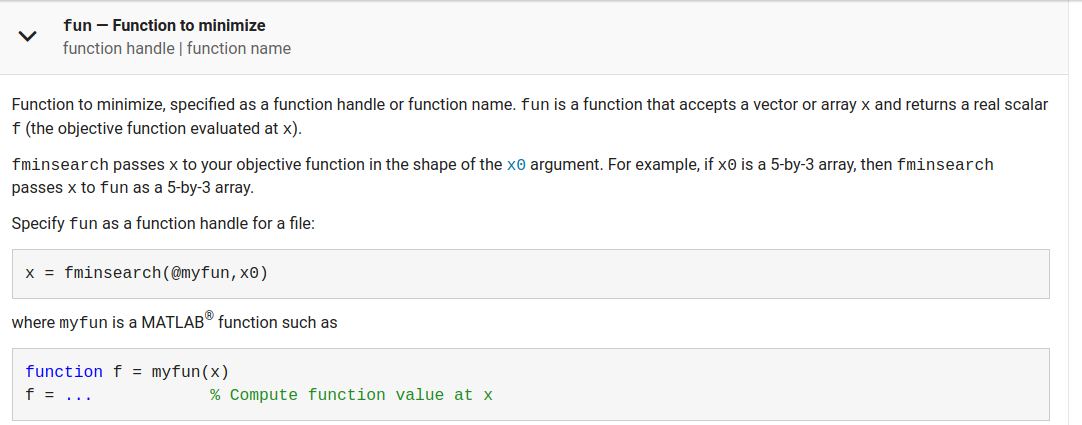

So the crux of the problem is to define a single function with input of the parameters ($K$and $n$) as a two element vector and provides the least-squares cost as the output.  Here is an outline of how you might combine the pieces above to accomplish this.  You should besically be able to copy-paste eleements from above into a single function.

function MSE = ROE_mse(params)
    
    % 1. Copy-Paste the experimental data into the function
    % Strain [mm/mm]
    strain_exp = [0, 0.0023809 0.003749347, 0.005234888, ...
        0.007631515, 0.011446096, 0.017384888, ...
        0.026405375, 0.039775799];
    % Stress [MPa]
    stress_exp = [0, 500, 550, 600, 660, 720, 780, 840, 900];

    % 2. Call the ROE local function (which we already wrote above) for
    % the experimental strain values - and for the parameter K and n.
    strain = ROE(stress_exp, params);

    % 3. Calculate the mean square error.
    cost = sum((strain-strain_exp).^2);
end

params_opt = 1.0e+03 *

   1.480091858460030   0.006708291764990


MSE_opt =      5.211433164271234e-07


## Apply the optimization algorithm

Call the `fminsearch` solver, providing it with the function handle to your cost function and the initial estimate of parameters.  The algorithm, if successful, will return the parameters (K and n) that minimize the cost funtion and the minimum cost (MSE) at those values.

params0 = [1000, 5];
[params_opt, MSE_opt] = fminsearch(@ROE_mse, params0)

## Verify and quantify goodness-of-fit

We will verify the results qualitatively by plotting the ROE model over a range of stress values and plotting that functional relationship on the same axes as the experimental data.

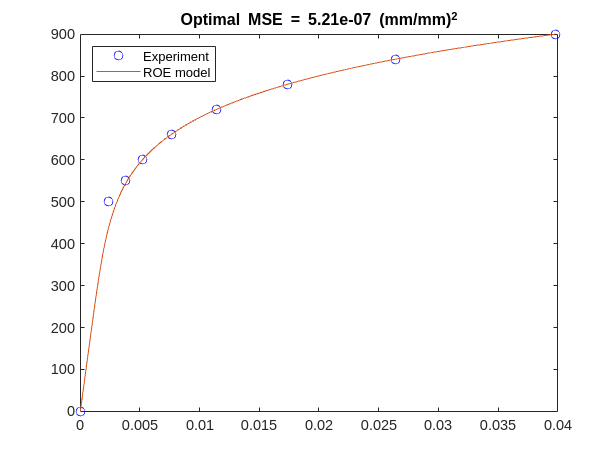

stress = linspace(stress_exp(1), stress_exp(end), 100);
strain = ROE(stress, params_opt);

figure;
clf;
plot(strain_exp, stress_exp,'bo')
hold on
plot(strain, stress)

legend('Experiment', 'ROE model', 'location','northwest')

The MSE metric is one way to quantify how well the model explains the fit.  Use `sprintf` command to add a title to the figure that includes the numeric value of the MSE, and untites, for the model parameters that fminsearch found.

title(sprintf("Optimal MSE = %.2e (mm/mm)^2", MSE_opt))

## Optional - Problem Exploration

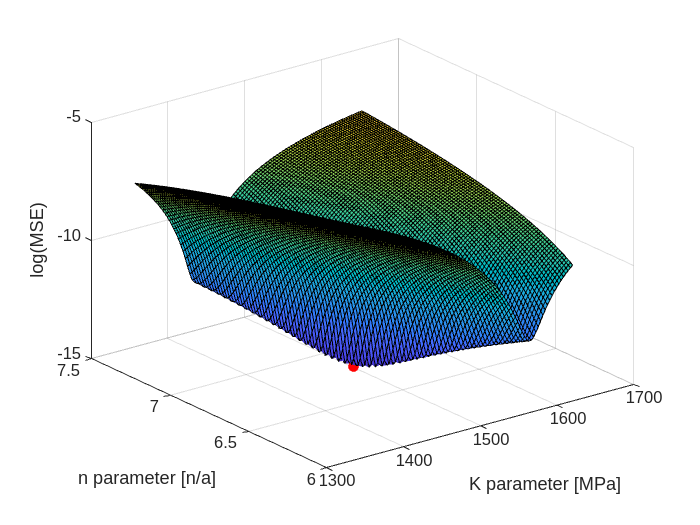

kk = linspace(params_opt(1)*0.9, params_opt(1)*1.1, 100);
nn = linspace(params_opt(2)*0.9, params_opt(2)*1.1, 100);
[KK, NN] = meshgrid(kk,nn);
clear ZZ
for ii = 1:size(KK,1)
    for jj = 1:size(KK,2)
        ZZ(ii,jj) = ROE_mse([KK(ii,jj), NN(ii,jj)]);
    end
end
figure;
clf;
surf(KK,NN, log(ZZ))
hold on
plot3(params_opt(1), params_opt(2), log(MSE_opt), 'ro', 'MarkerFaceColor','r')

xlabel('K parameter [MPa]')
ylabel('n parameter [n/a]')
zlabel('log(MSE)')

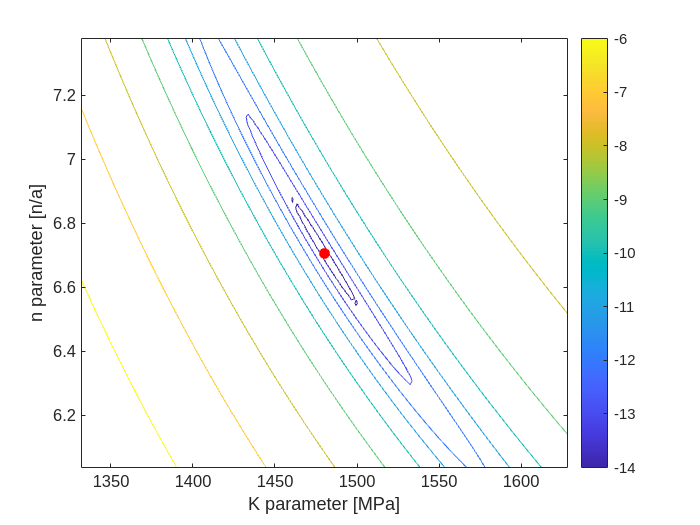

figure;
clf;
contour(KK,NN,log(ZZ))
hold on
plot(params_opt(1), params_opt(2), 'ro', 'MarkerFaceColor','r')
xlabel('K parameter [MPa]')

ylabel('n parameter [n/a]')
colorbar